# サッカーにおける攻撃力・守備力モデル

clear;clc;close all;

Jリーグの試合データの読み込み

tbl_results=readtable('../data/JLeagueResults.xlsx');
tbl_results.Category=categorical(tbl_results.Category);
tbl_results.HomeE=categorical(tbl_results.HomeE);
tbl_results.AwayE=categorical(tbl_results.AwayE);

ここ5年程度のJ1リーグのみ抽出

ind = tbl_results.Year<=2023 & tbl_results.Year>=2019 ...
    & tbl_results.Category=='Ｊ１';
tbl_results=tbl_results(ind,:);
seasonStartYearVals=unique(tbl_results.Year);

予測性能を保存する変数を用意する

PredictedMatches=[];    %予測対象の試合数
CorrectsByMassey=[];    %Masseyで予測した予測正解数

計算を早くするため，チーム名などを数値に変換しておく

matchData=zeros(size(tbl_results,1),4);
teamNames=unique([tbl_results.HomeE;tbl_results.AwayE]);
for n1=1:size(tbl_results,1)
    TeamAName=tbl_results.HomeE(n1);
    TeamBName=tbl_results.AwayE(n1);
    TeamANum=find(teamNames== TeamAName);
    TeamBNum=find(teamNames== TeamBName);
    matchData(n1,1)=TeamANum;
    matchData(n1,2)=TeamBNum;
    matchData(n1,3)=tbl_results.HomeGoals(n1);
    matchData(n1,4)=tbl_results.AwayGoals(n1);
end

### レーティングを計算する

- シーズンが変わった時に初期化する

- 日付が変わったらレーティングを計算する

- 予測対象試合でなくても計算しておく(予測対象試合は後で抽出しなおす)

r=zeros(size(teamNames,1)*2+1,1);
r_O=r(1:size(teamNames,1));
r_D=r(size(teamNames,1)+1:end-1);
r_homeAdv=r(end);

RatingValus=zeros(size(matchData,1),4);
tbl_results=sortrows(tbl_results,"Date");


for n1=1:size(tbl_results,1)
    if n1>1 && ...
            (tbl_results.Year(n1)>tbl_results.Year(n1-1))
        % 年が変わったらレーティングを初期化する
        r=zeros(size(teamNames,1)*2+1,1);
    end

    if n1>1 && ...
            (tbl_results.Date(n1)>tbl_results.Date(n1-1))

        % 日付が変わったらレーティングを更新する
        ind = (tbl_results.Year==tbl_results.Year(n1)) ...
            & tbl_results.Date< tbl_results.Date(n1);
        tmpMatchData=matchData(ind,:);

        % 1試合で2行の条件式が現れる
        X=zeros(size(tmpMatchData,1)*2, size(teamNames,1)*2+1);
        y=zeros(size(tmpMatchData,1)*2,1);
        for n2=1:size(tmpMatchData,1)
            TeamANum=tmpMatchData(n2,1);
            TeamBNum=tmpMatchData(n2,2);
            TeamAGoals=tmpMatchData(n2,3);
            TeamBGoals=tmpMatchData(n2,4);
            X(2*n2-1,TeamANum)=1;
            X(2*n2-1,size(teamNames,1)+TeamBNum)=-1;
            X(2*n2-1,end)=1;
            y(2*n2-1)=TeamAGoals;
            
            X(2*n2,TeamBNum)=1;
            X(2*n2,size(teamNames,1)+TeamANum)=-1;
            X(2*n2,end)=0;
            y(2*n2)=TeamBGoals;
        end
        r=pinv(X)*y;
        r_O=r(1:size(teamNames,1));
        r_D=r(size(teamNames,1)+1:end-1);
        r_homeAdv=r(end);
    end

    TeamANum=matchData(n1,1);
    TeamBNum=matchData(n1,2);

    RatingValus(n1,:) ...
        =[r_O(TeamANum)+r_homeAdv r_D(TeamANum) ...
        r_O(TeamBNum) r_D(TeamBNum)];

end


レーティングによる勝敗予測

PredictionByRating= ...
    RatingValus(:,1)-RatingValus(:,4) ...
    >RatingValus(:,3)-RatingValus(:,2);

実際の勝敗

ActualWin=matchData(:,3)>matchData(:,4);
ActualDraw=matchData(:,3)==matchData(:,4);


シーズン開始年を指定しそれぞれについて集計する．

PredGoals=[];ActualGoals=[];
for seasonStartYearVal=seasonStartYearVals'
    seasonStartYearVal
    ind = tbl_results.Year==seasonStartYearVal;

seasonStartYearVal = 2019

seasonStartYearVal = 2020

seasonStartYearVal = 2021

seasonStartYearVal = 2022

seasonStartYearVal = 2023

予測対象の開始日を求める

    seasonStartDate=min(tbl_results.Date(ind));
    predictionStartDate=seasonStartDate+days(31);

テスト用(test)の試合結果の表を作る

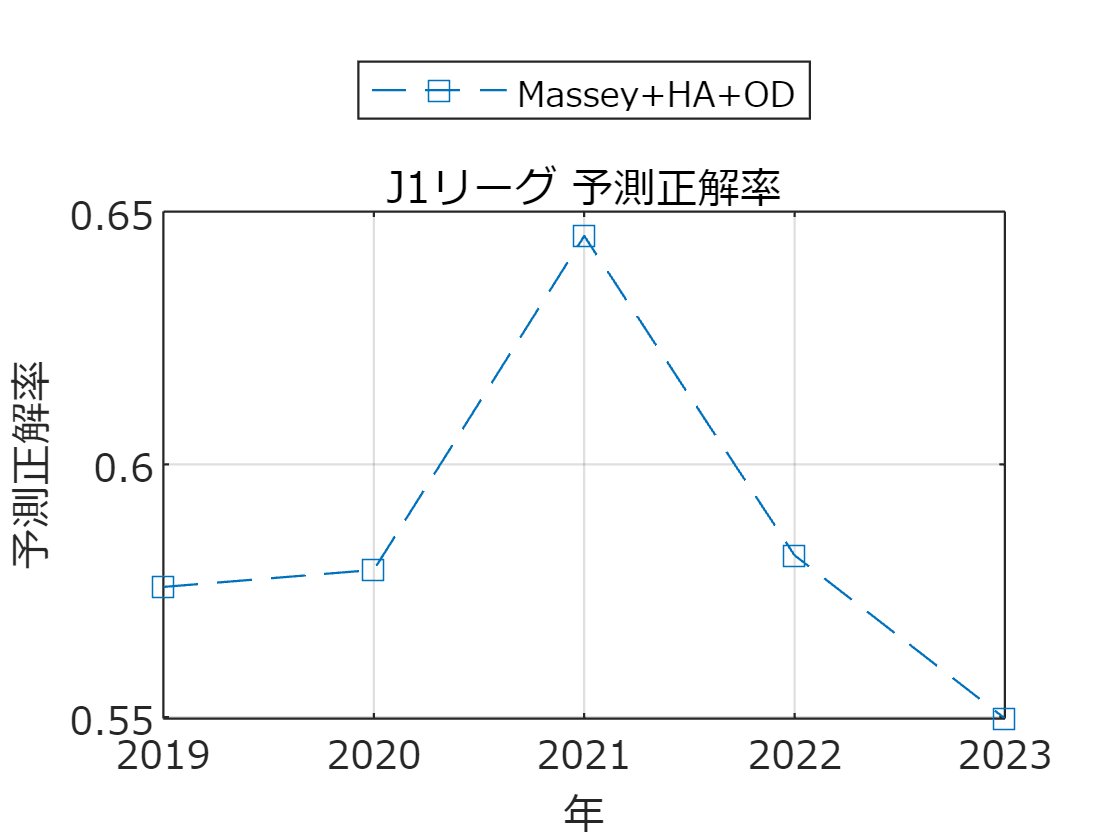

    ind = tbl_results.Year==seasonStartYearVal ...
        & tbl_results.Date>=predictionStartDate;

    PredictedMatches=[PredictedMatches;sum(ind)];
    CorrectsByMassey=[CorrectsByMassey;...
        sum(PredictionByRating(ind)==ActualWin(ind))];
    PredGoals=[PredGoals;

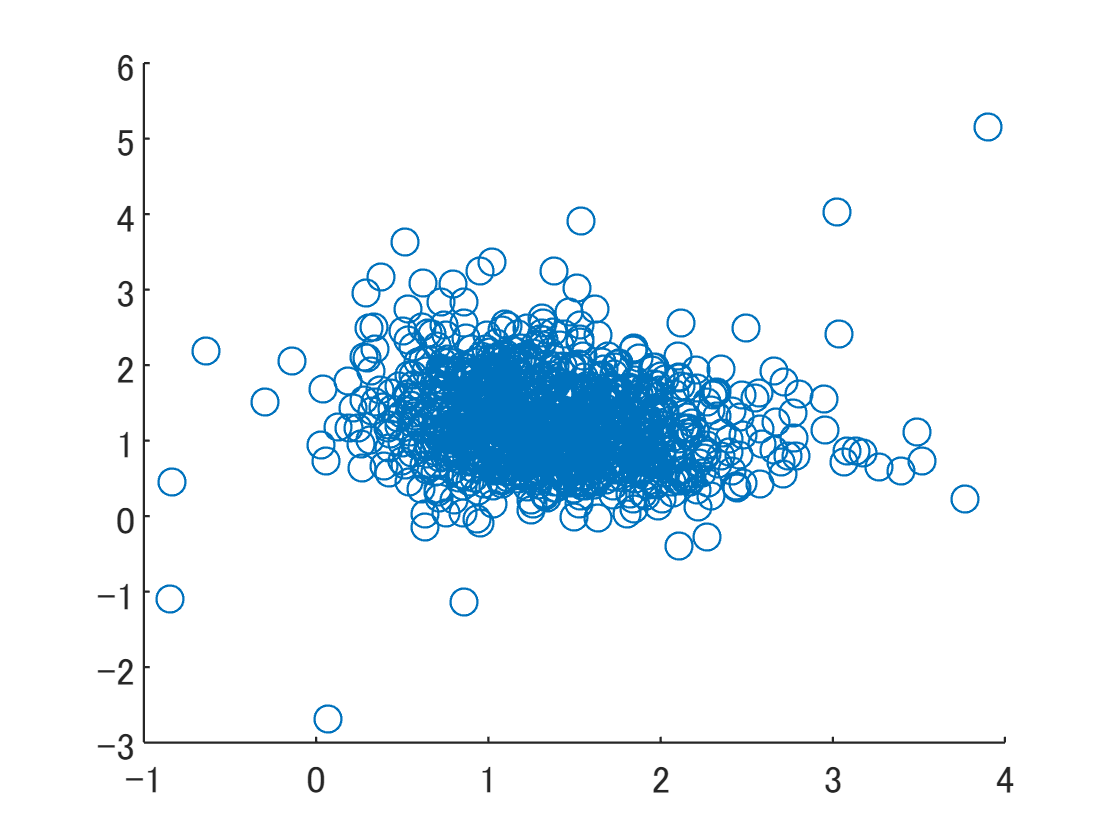

        (RatingValus(ind,1)-RatingValus(ind,4)) ...
        (RatingValus(ind,3)-RatingValus(ind,2));
        ];

    ActualGoals=[ActualGoals;
        matchData(ind,3) ...
        matchData(ind,4)];
end

図示する

figure;
plot(seasonStartYearVals, CorrectsByMassey./PredictedMatches,'s--');
hold on;grid on;

set(gca,'fontname','メイリオ');
xlabel('年');ylabel('予測正解率');
legend({'Massey+HA+OD'},'Location','northoutside');
title('J1リーグ 予測正解率');
exportgraphics(gcf,'fig_J1PredictionByPairwise-OD-ByDate.pdf');

予測得点と実得点

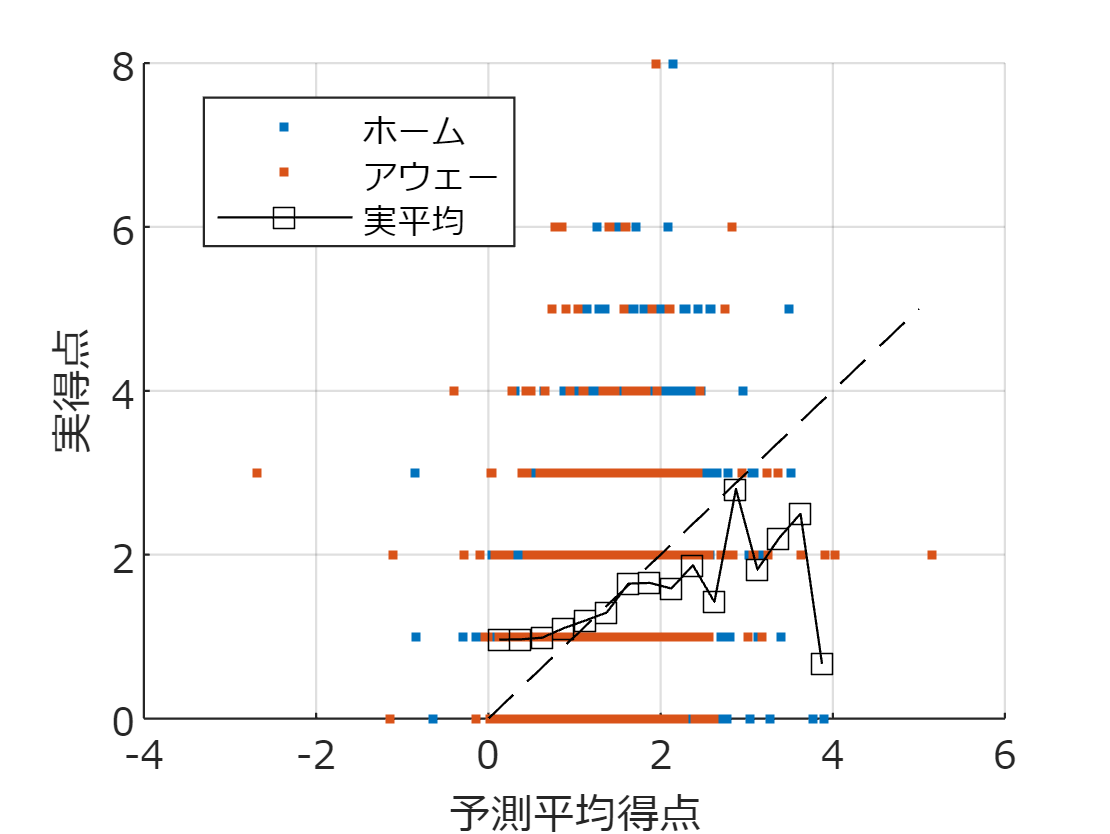

figure;
scatter(PredGoals(:,1), PredGoals(:,2));

figure;
scatter(PredGoals, ActualGoals,'.');
set(gca,'fontname','メイリオ');

grid on;hold on;xlabel('予測平均得点');ylabel('実得点');

bins=0:0.25:4;
hc=[];
for n1=unique(ActualGoals)'
    ind = ActualGoals==n1;
    hc=[hc;histcounts(PredGoals(ind), bins)];
end

predWDL =     0.3357    0.2164    0.4479
    0.5457    0.1999    0.2544
    0.1884    0.3607    0.4509
    0.4711    0.2715    0.2575
    0.0963    0.2134    0.6903
    0.2345    0.4241    0.3415
    0.7696    0.1618    0.0686
    0.2541    0.2149    0.5310
    0.2618    0.3689    0.3693
    0.2885    0.2168    0.4948



plot(movmean(bins,2,"Endpoints","discard"), ...
    (hc'*unique(ActualGoals))./sum(hc)', ...
    'ks-');
plot([0 5],[0 5],'k--')
legend({'ホーム','アウェー','実平均'},'Location','best')

ActualWDL = 1092×3 の logical 配列
   1   0   0
   0   1   0
   1   0   0
   1   0   0
   1   0   0
   0   0   1
   0   0   1
   1   0   0
   0   0   1
   0   0   1


exportgraphics(gcf,'fig_J1PredAndActualGoals-OD-ByDate.pdf');

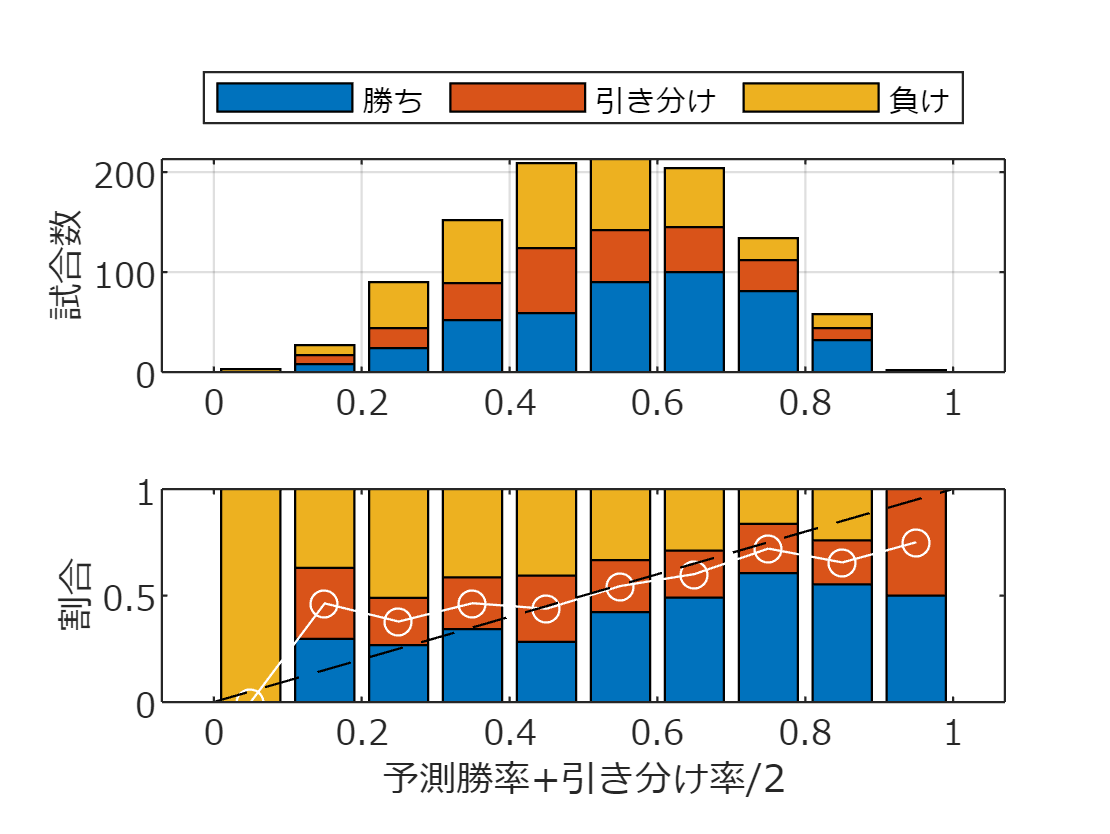


minGoals=0.5;maxGoals=3;
GF=PredGoals(:,1);GA=PredGoals(:,2);
GF=min(max(GF,minGoals),maxGoals);
GA=min(max(GA,minGoals),maxGoals);
predWDL= predByPoisson(GF, GA)

ActualWDL=[ ...
    ActualGoals(:,1)>ActualGoals(:,2) ...
    ActualGoals(:,1)==ActualGoals(:,2) ...
    ActualGoals(:,1)<ActualGoals(:,2) ...
    ]

hc=[];
bins=0:0.1:1;
tmpVal=predWDL(ActualWDL(:,1),1)+predWDL(ActualWDL(:,1),2)/2;
hc=[hc;histcounts(tmpVal,bins)];

tmpVal=predWDL(ActualWDL(:,2),1)+predWDL(ActualWDL(:,2),2)/2;
hc=[hc;histcounts(tmpVal,bins)];

tmpVal=predWDL(ActualWDL(:,3),1)+predWDL(ActualWDL(:,3),2)/2;
hc=[hc;histcounts(tmpVal,bins)];

figure
tiledlayout(2,1);nexttile;
bar( movmean(bins,2,"Endpoints","discard"), hc, "stacked");
set(gca,'fontname','メイリオ');grid on;

ylabel('試合数');
legend({'勝ち','引き分け','負け'},'Location','northoutside','Orientation','horizontal');
nexttile;
bar( movmean(bins,2,"Endpoints","discard"), ...
    hc./sum(hc), "stacked");
hold on;
plot(movmean(bins,2,"Endpoints","discard"), ...
    (hc(1,:)+hc(2,:)/2)./sum(hc), 'wo-');
plot([0 1],[0 1],'k--')
set(gca,'fontname','メイリオ');
ylabel('割合');
xlabel('予測勝率+引き分け率/2')
exportgraphics(gcf,'fig_J1PredictionPerformanceByPairwiseODByDate.pdf');